# ReciclarIA

## 1. Carga de los datos

Nuestro dataset consiste de una serie de fotografias

% Eliminamos variables y valores previos
clear; clc; close all

% Definimos la ruta donde tenemos el dataset
datasetPath = 'C:\Users\murci\Documents\Master_IA\Redes_Neuronales\ReciclarIA\RealWaste'; 

% Creamos el datastore --> cada subcarpeta tiene nombre de label/etiquetas
imds = imageDatastore(datasetPath, ...
    'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames');

disp("Datos cargados correctamente.");

Datos cargados correctamente.



% Ver distribución de clases (opcional)
countEachLabel(imds)

ans = 9×2 table
           Label           Count
    ___________________    _____

    Cardboard               461 
    Food Organics           411 
    Glass                   420 
    Metal                   790 
    Miscellaneous Trash     495 
    Paper                   500 
    Plastic                 921 
    Textile Trash           318 
    Vegetation              436 



% Dividir los datos: 70% entrenamiento, 15% validación, 15% prueba
[imdsTrain, imdsVal, imdsTest] = splitEachLabel(imds, 0.7, 0.15, 'randomized');

## 2. Preprocesamiento de las imagenes

imageSize = [224 224 3]; % Alto, Ancho, Canales (RGB)

% Augmentador de datos (Opcional pero recomendado para evitar Overfitting)
% Esto crea variaciones aleatorias (giros, espejos) de tus imágenes
augimdsTrain = augmentedImageDatastore(imageSize, imdsTrain, ...
    'ColorPreprocessing', 'gray2rgb'); % Asegura que sean RGB
augimdsVal = augmentedImageDatastore(imageSize, imdsVal, ...
    'ColorPreprocessing', 'gray2rgb');

## 3.Definir la Arquitectura de la CNN

layers = [
    imageInputLayer(imageSize)
    
    % Primer bloque convolucional
    convolution2dLayer(3, 8, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)
    
    % Segundo bloque convolucional
    convolution2dLayer(3, 16, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)
    
    % Tercer bloque convolucional
    convolution2dLayer(3, 32, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)
    
    % Capas finales de clasificación
    fullyConnectedLayer(numel(unique(imds.Labels))) % Número de clases
    softmaxLayer
    classificationLayer];

## 4. Configuracion del entrenamiento

options = trainingOptions('sgdm', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs', 15, ... % Número de veces que pasará por todo el dataset
    'MiniBatchSize', 32, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', augimdsVal, ...
    'ValidationFrequency', 30, ...
    'Verbose', false, ...
    'Plots', 'training-progress');

## 5. Entrenamiento de la red

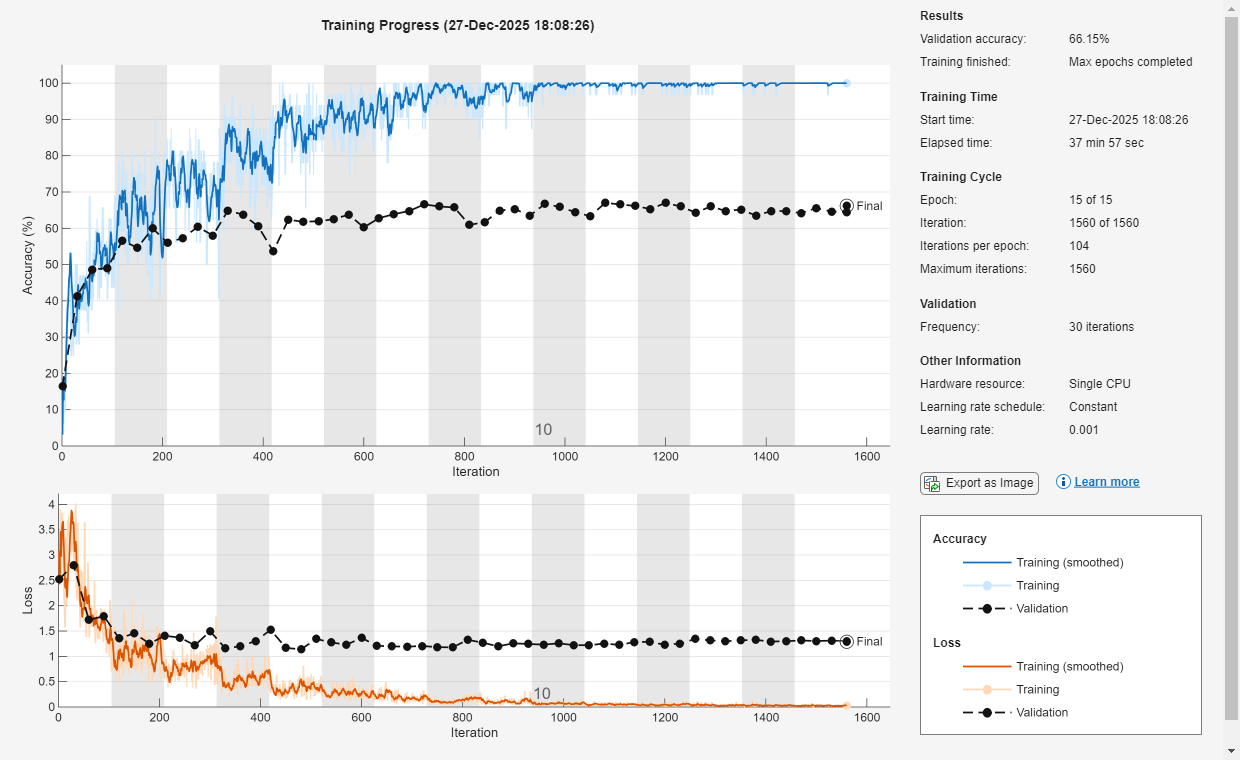

net = trainNetwork(augimdsTrain, layers, options);

## 6. Evaluacion del modelo

% Preprocesar el set de prueba igual que el de entrenamiento
augimdsTest = augmentedImageDatastore(imageSize, imdsTest, ...
    'ColorPreprocessing', 'gray2rgb');

% Clasificar las imágenes de prueba
[YPred, probs] = classify(net, augimdsTest);
YTest = imdsTest.Labels;

% Calcular la precisión global
accuracy = mean(YPred == YTest);
disp(['Precisión del modelo: ', num2str(accuracy * 100), '%']);

Precisión del modelo: 64.6067%


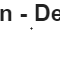


% Visualizar la Matriz de Confusión
figure
confusionchart(YTest, YPred)
title('Matriz de Confusión - Detector de Residuos')

## 7. Guardado del modelo

% Definimos el nombre del archivo donde se guardará el modelo
modelFileName = 'ModeloReciclarIA_Entrenado.mat';

% Guardamos la variable 'net' que contiene nuestra red neuronal
save(modelFileName, 'net');

disp(['Modelo guardado exitosamente como: ', modelFileName]);

Modelo guardado exitosamente como: ModeloReciclarIA_Entrenado.mat


## 8. Prueba del modelo entrenado

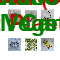

% Cargamos el modelo previamente guardado (esto asegura que la prueba sea real)
dataLoaded = load('ModeloReciclarIA_Entrenado.mat');
netCargada = dataLoaded.net;

figure;
idx = randperm(numel(imdsTest.Files), 6); % Seleccionamos 6 imágenes al azar

for i = 1:6
    subplot(2,3,i)
    img = readimage(imdsTest, idx(i));
    imshow(img)
    
    % Obtenemos la etiqueta real
    actualLabel = YTest(idx(i));
    
    % Realizamos la predicción usando el modelo CARGADO
    % Es necesario redimensionar si se procesan imágenes individuales
    imgResized = imresize(img, [224 224]);
    [predictedLabel, probs_single] = classify(netCargada, imgResized);
    conf = max(probs_single) * 100; 
    
    title(sprintf("Pred: %s (%.1f%%)\nReal: %s", ...
        string(predictedLabel), conf, string(actualLabel)));
    
    % Si acierta, título en verde; si falla, en rojo
    if actualLabel == predictedLabel
        color = [0 0.5 0]; 
    else
        color = [0.8 0 0];
    end
    t = get(gca, 'Title');
    set(t, 'Color', color);
end